# Ultimate Brownie Pan Code

## Input Curves and Shapes Plotted

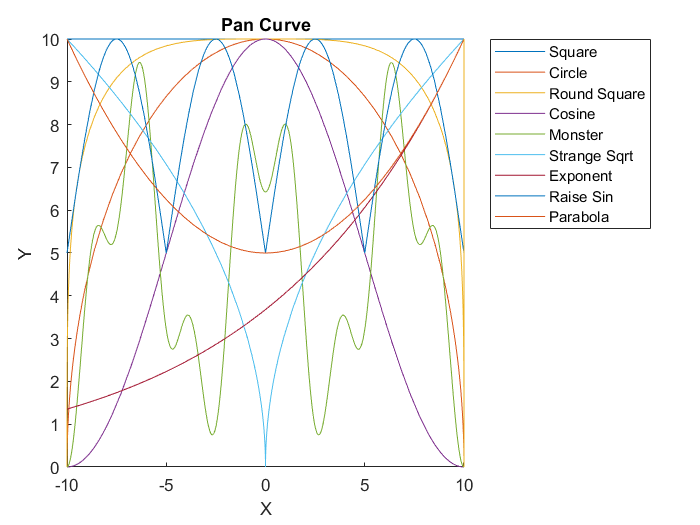

points = 100; %Set the number of data points that will be used throughout this program.
warning('off');

f = {@(x, k)(k.*(x.^0)); @(x, k)sqrt(k.^2-x.^2); @(x, k)(k.^4-x.^4).^(1/4); @(x,k)k/2.*cos(pi.*x./k)+k/2; ...
    @(x,k)9/7*(k/4.*sin(4*pi.*x./k).^2+k./4.*cos(3*pi*x./k)+k/4); @(x,k)((x.^2).^(1/4).*sqrt(k));...
    @(x,k)(exp(x./k-1).*k); @(x,k)(k/2.*(1+abs(sin(2*pi*x./k)))); @(x,k)((x.^2)./(2*k)+k/2)}; %Get the functions that will be used for pans, must be anon functions with 2 parameters

func = size(f);
func = func(1); %Get how many functions are in the input array
figure(1) %Create first figure
for i = 1:func
    hold on;
    fplot(@(x)f{i}(x, 10), [-10, 10]) %Plot all of our functions on the range -10, 10. This is an arbitrary range however
end
shapeNames = {'Square', 'Circle', 'Round Square', 'Cosine', 'Monster', 'Strange Sqrt', 'Exponent'...
    'Raise Sin', 'Parabola'}; %Create an array of names for future legends
plot([10, 10], [10, 0]) %Add another side to the square, since its a piecewise function
legend(shapeNames, 'Location','bestoutside'); %Don't want the legend to cover the function
title('Pan Curve') %Label the graph
xlabel('X')
ylabel('Y')

## Area of a Region Given the Side Length

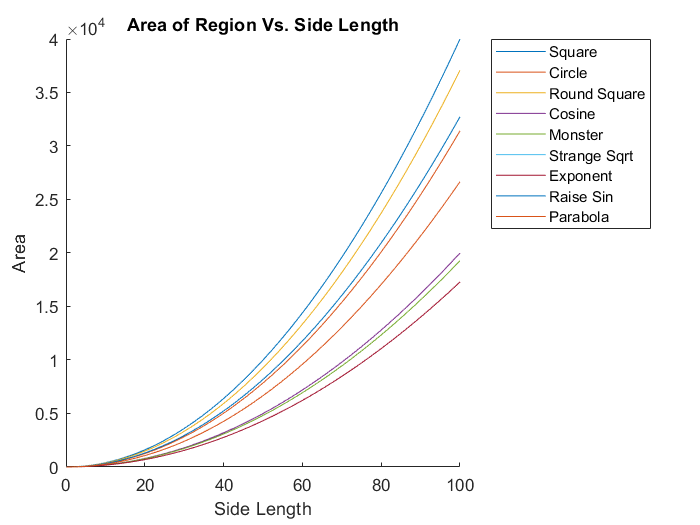

Area = cell(func); %Create an array to house all the arrays of areas
figure(2) %Create a new figure
for i = 1:func
    Area{i} = @(k) 2*integral(@(x)f{i}(x,k), -k, k); %Get the areas for every side length value and then plot it
    hold on;
    fplot(Area{i}, [0, points])
end
xlabel('Side Length') %Label the graphs
ylabel('Area')
title('Area of Region Vs. Side Length')
legend(shapeNames, 'Location','bestoutside')

## Side Length of a Region Given the Area

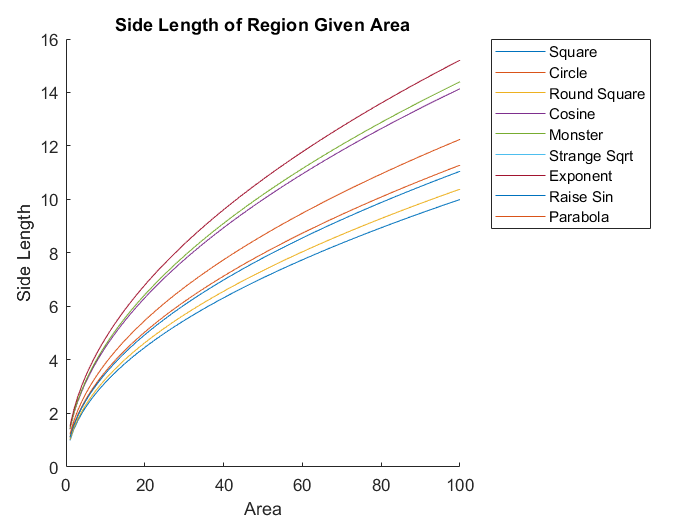

figure(3) %Create a new chart
iters = 10; %We will iterate Newton's method 10 times
delta = .0001; %Small number for approximating derivatives
Length = zeros(points, func); %Create a bunch of arrays of zeros to house the lengths
for a = 1:func %Loop for every curve
    for i = 1:points %Find the appropriate side length for each Area value
        xn = 3; %Initial guess. Not a bad guess for smaller values of A
        for j = 1:iters
            xn = xn - (feval(@(y)Area{a}(y)-i, xn)/((feval(@(y)Area{a}(y)-i, xn+delta) - feval(@(y)Area{a}(y)-i, xn-delta))/(2*delta))); %Newton's Method
        end
        Length(i,a) = xn*2; %Adjust since I divided the area by 4 before
    end
    hold on;
    plot(Length(:,a)) %Plot the lengths
end
xlabel('Area') %Label the graphs
ylabel('Side Length')
title('Side Length of Region Given Area')
legend(shapeNames, 'Location','bestoutside')

## Wasted Space of a Given Pan

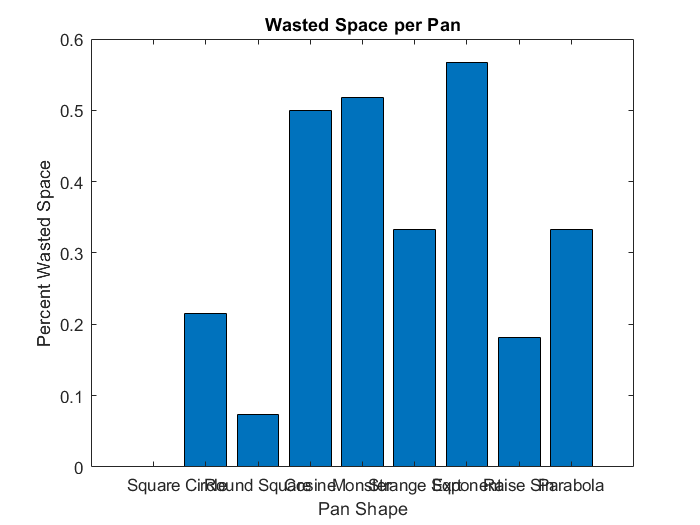

figure(4) %Create a new chart
wastedSpace = zeros(func, 1);
for i = 1:func
    wastedSpace(i) = 1 - Area{i}(Length(5, i)/2) /(Length(5, i)^2); %Calculate the wasted space relative the enclosing square
end
bar(wastedSpace); %Make a bar chart
title('Wasted Space per Pan') %Label the graph
xlabel('Pan Shape')
ylabel('Percent Wasted Space')
set(gca, 'xticklabel', shapeNames)

## Heat Distribution on Pans

figure(5) %Create a new chart
area = 20; %Get the input area
radius = Length(area, 1) %Find the appropriate radius for the area we are given

radius = 4.4721

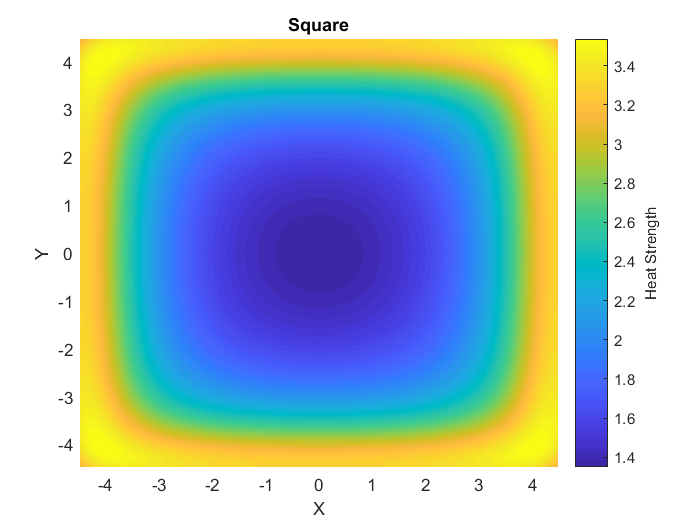

radius = 4.4721

radius = 5.0463

radius = 4.6448

radius = 6.3246

radius = 6.4406

radius = 5.4772

radius = 6.8015

radius = 4.9437

radius = 5.4772

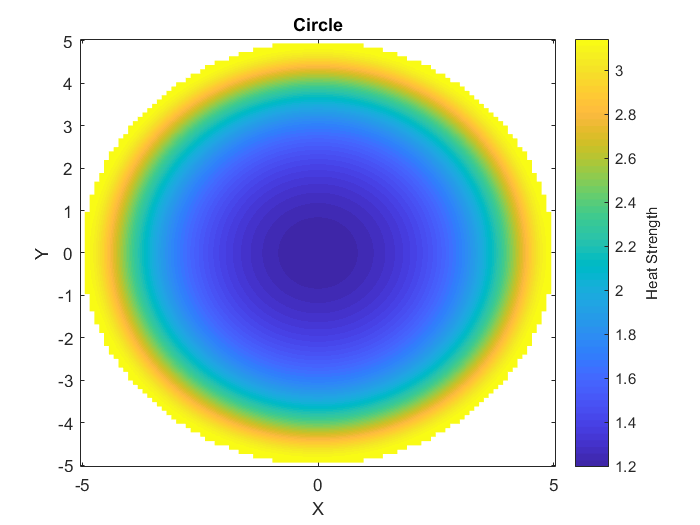

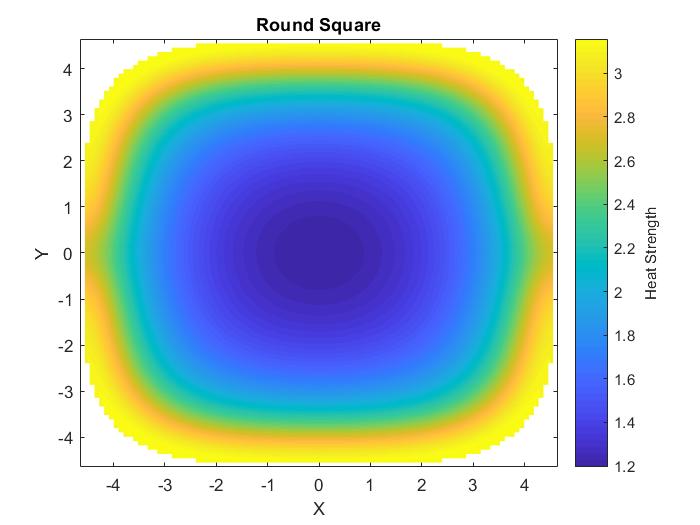

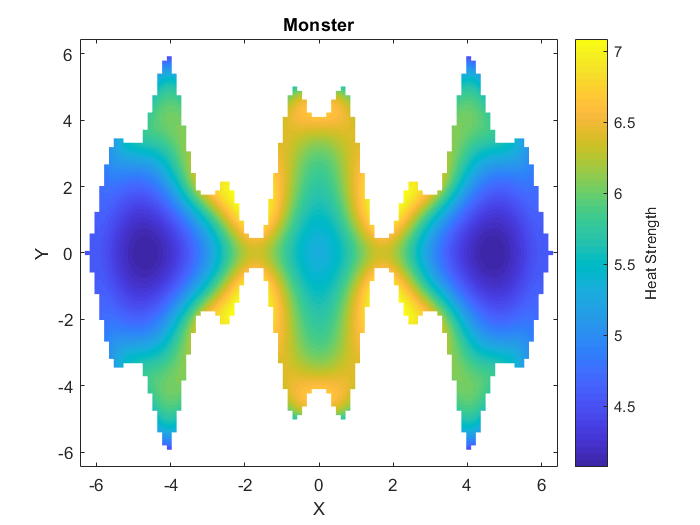

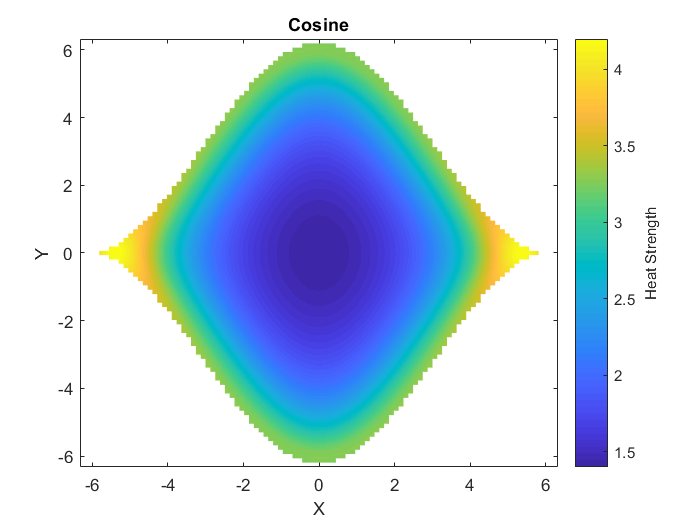

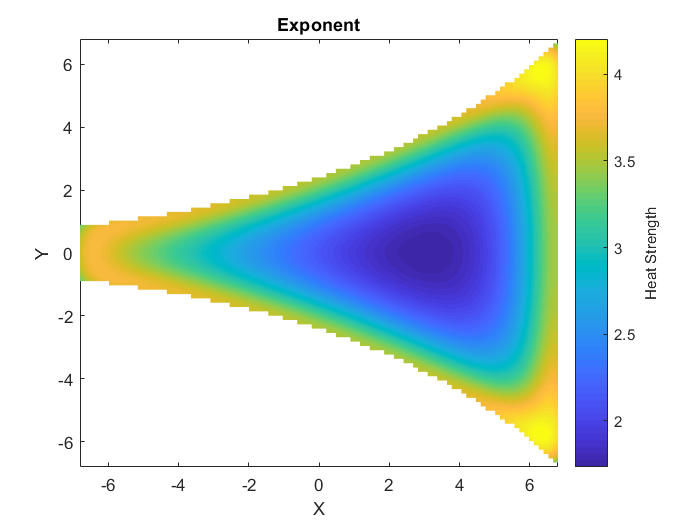

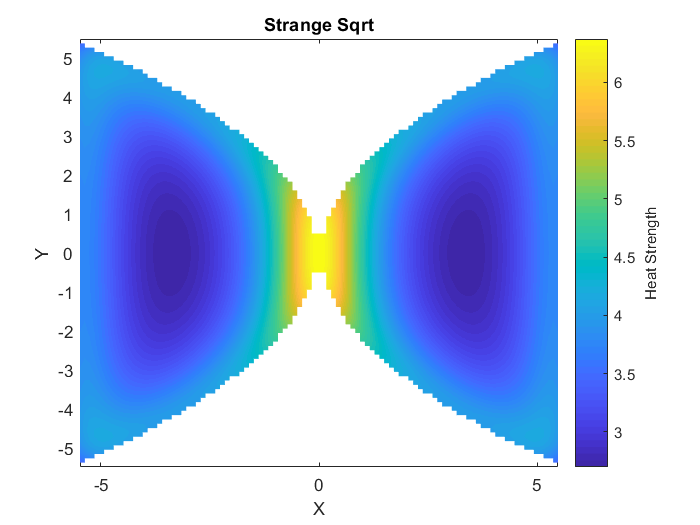

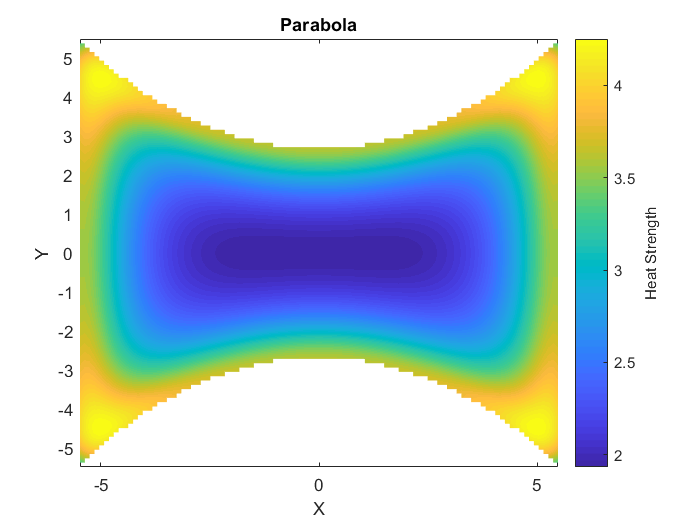

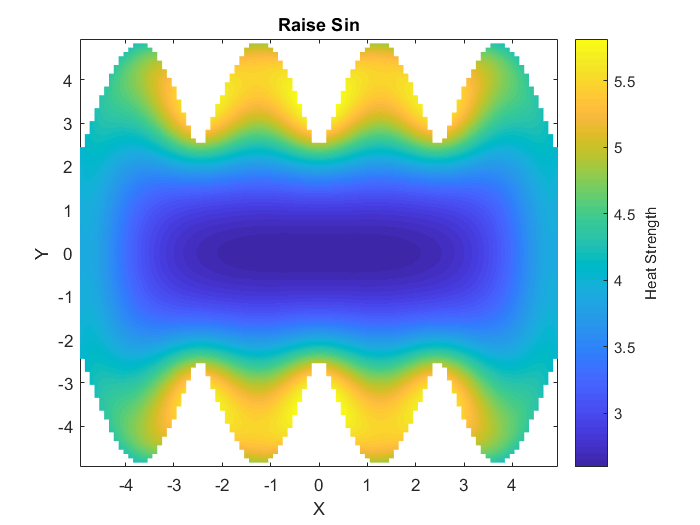

x=linspace(-radius, radius, points); 
y=linspace(-radius, radius, points);
[X,Y]=meshgrid(x,y); %Create a mesh of points so that we can visualize the entire pan
Z = NaN(points, points, func); %Create a mesh of values of the temperature. Initialize to NaN so that we can ignore what's outside the pans
sqth = @(a,b)sqrt((a-b).^2+1); %Helper function
%This is the closed form of the heat equation of the square. Since it is a piecewise curve, we use this instead of the approximation lower down
% Z(:,:,1) = atan((radius-X)./sqth(radius, Y))./sqth(radius, Y)-atan((-radius-X)./sqth(radius,Y))./sqth(radius,Y)...
%           +atan((radius+Y)./sqth(radius, X))./sqth(radius, X)-atan((Y-radius)./sqth(radius,X))./sqth(radius,X)...
%           +atan((radius-X)./sqth(-radius, Y))./sqth(-radius, Y)-atan((-radius-X)./sqth(-radius,Y))./sqth(-radius,Y)...
%           +atan((radius+Y)./sqth(-radius, X))./sqth(-radius, X)-atan((Y-radius)./sqth(-radius,X))./sqth(-radius,X);
% pcolor(X,Y,Z(:,:,1)); %Plot the square chart
% shading('interp') %Color and label the square chart
% c = colorbar;
% c.Label.String = 'Heat Strength';
% xlabel('X')
% ylabel('Y')
% title(shapeNames{1})

for a = 1:func %Do the Heat chart of the other shapes
    figure(4+a) %Create a new chart
    radius = Length(area, a) %Find the radius for the given area
    x=linspace(-radius, radius, points);
    y=linspace(-radius, radius, points);
    %This is the approximation function for a curve reflected across the y-axis. Section 7 of the write-up includes an explanation
    test = @(u,v)(integral(@(t)(((abs(f{a}(t+delta,radius)-f{a}(t-delta, radius))/(delta*2)).^2+1).^(1/2)./(1+(t-u).^2+(f{a}(t,radius)-v).^2)),-radius,radius)...
        +integral(@(t)(((abs(f{a}(t+delta,radius)-f{a}(t-delta, radius))/(delta*2)).^2+1).^(1/2)./(1+(t-u).^2+(-f{a}(t,radius)-v).^2)),-radius,radius))...
        +atan((f{a}(radius, radius)-v)/sqth(u, radius))/sqth(u, radius)-atan((-f{a}(radius, radius)-v)/sqth(u, radius))/sqth(u, radius)...
        +atan((f{a}(-radius, radius)-v)/sqth(u, -radius))/sqth(u, -radius)-atan((-f{a}(-radius, radius)-v)/sqth(u, -radius))/sqth(u, -radius);
    
    [X,Y]=meshgrid(x,y); % Create a mesh of points
    for i = 1:points %Loop through every point on the plane
        for j = 1:points
            if(f{a}(x(i), radius)<y(j) || -f{a}(x(i),radius)>y(j)) %If it outside the region, skip it
                continue
            end
            val = test(x(i), y(j));
            Z(j, i, a) = test(x(i), y(j)); %Assign the value to the appropriate location in the region
        end
    end
    pcolor(X,Y,Z(:,:,a)); %Create a plot and label it
    c = colorbar;
    c.Label.String = 'Heat Strength';
    shading('interp')
    
    hold on;
    xlabel('X')
    ylabel('Y')
    title(shapeNames{a})
end

## Data Analytics and Quantifying the Best Pan

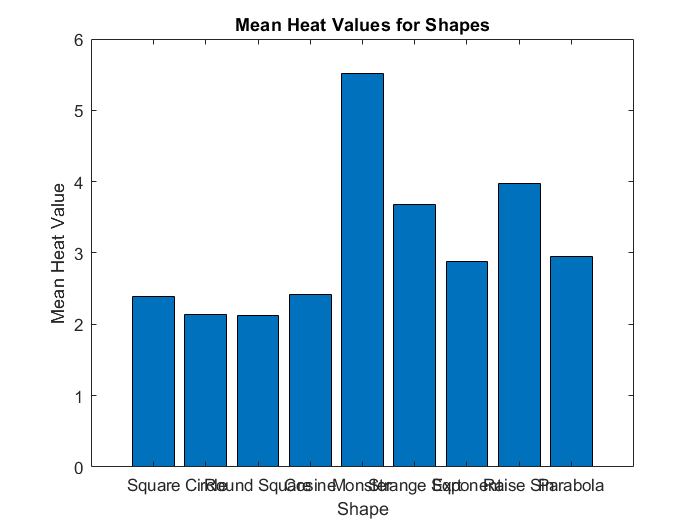

means = zeros(func, 1); %Create arrays for the means, Stds, and results
stds = means;
quants = @(x,y,z)((1-z)./(x.*y)); %Formula for determining the strength score of the pan
results = means;
for i = 1:func %Loop through every possible pan shape
    A = Z(:,:,i); %Create an array of every value for a particular mesh
    means(i) = nanmean(A(:)); %Take mean and standard deviation of all values ignoring the NaNs
    stds(i) = nanstd(A(:));
    results(i) = quants(means(i), stds(i), wastedSpace(i)); %Calculate the strength score
end
figure(5+func) %Create the appropriate charts and label them appropriately
bar(means)
set(gca, 'xticklabel', shapeNames)
xlabel('Shape')
ylabel('Mean Heat Value')
title('Mean Heat Values for Shapes')

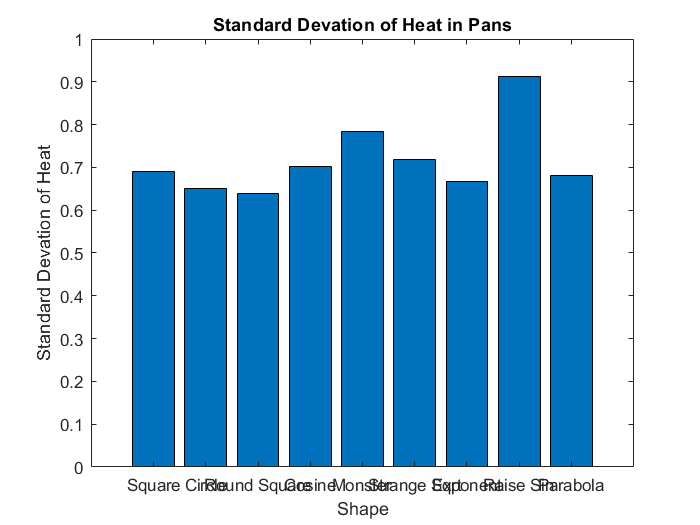


figure(6+func)
bar(stds)
set(gca, 'xticklabel', shapeNames)
xlabel('Shape')
ylabel('Standard Devation of Heat')
title('Standard Devation of Heat in Pans')

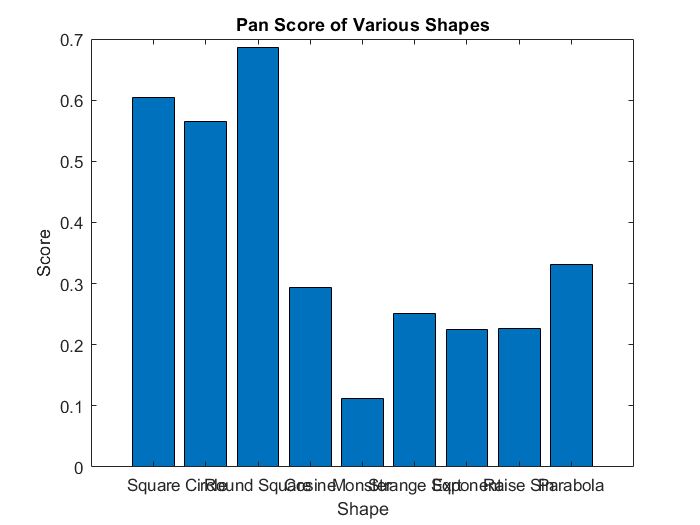


figure(7+func)
bar(results)
set(gca, 'xticklabel', shapeNames)
xlabel('Shape')
ylabel('Score')
title('Pan Score of Various Shapes')